# JacobiRelaxationMethod.m

This algorithm creates multiple plots to visualize the electric potential for a given spatial area, utilizing the Jacobi relaxation method.

## Define Paramaters

Vold = zeros(25);           % create vector with initial guesses of zero
Vold(:,1) = 1;              % set first boundary condition V(0) = 1V
Vold(:,25) = -1;            % set last boundary condition V(15) = -1V
Vnew = [];                  % create improved matrix
Vnew(:,1) = Vold(:,1);      % set boundary condition
Vnew(:,25) = Vold(:,25);    % set boundary condition
stepvec = 1:25;             % create step vector
stepsize = (1-0)/24;        % define the step size for each point
x = (stepvec-1)*stepsize;   % Create vector for x-axis point coordinates
y = (stepvec-1)*stepsize;   % Create vector for y-axis point coordinates
epsilon = length(Vold)*10.^-5;  % define convergence parameter
DV = 1000;                  % Set iterative residual to large number to enter while loop

## Calculations

while DV > epsilon
    
    for i = 2:1:24
        for j = 2:1:24
            % finite difference equation
            Vnew(i,j) = (1/4).*(Vold(i+1,j)+Vold(i-1,j)+Vold(i,j+1)+Vold(i,j-1));   
        end
    end
    
    DV=sum(sum(abs(Vnew-Vold)));    %iterative residual
    Vold = Vnew;                    %set Vold
end

%find max electric field magnitude and location
[U,V] = gradient(Vnew); 
maxU = max(max(U));
maxV = max(max(V));
magnitude = sqrt(maxU.^2+maxV.^2);

[maxUrow, maxUcolumn] = find(U == maxU);
[maxVrow, maxVcolumn] = find(V == maxV);

## Plotting

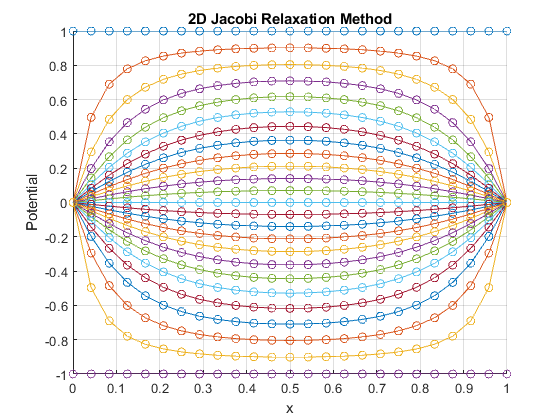

figure(1);

hold on;
grid on;
title('2D Jacobi Relaxation Method');
xlabel('x');
ylabel('Potential');
plot(x,Vnew,'-o')

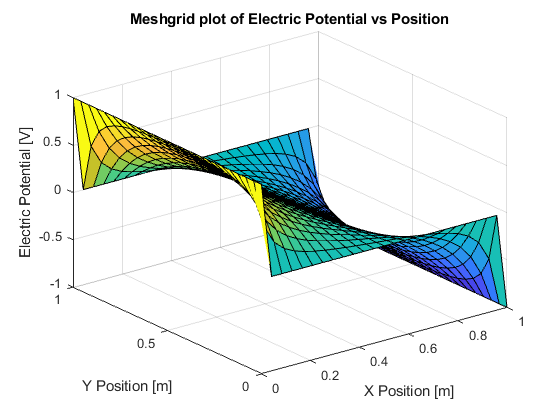


figure(2);

[X,Y]=meshgrid(x,y);
surf(X,Y,Vnew); title('Meshgrid plot of Electric Potential vs Position');
xlabel('X Position [m]');
ylabel('Y Position [m]');
zlabel('Electric Potential [V]');

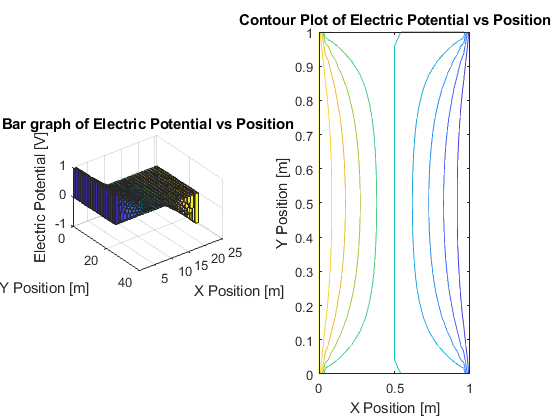


figure(3);

subplot(1,2,1); bar3(Vnew); 
title('Bar graph of Electric Potential vs Position');
xlabel('X Position [m]'); 
ylabel('Y Position [m]'); 
zlabel('Electric Potential [V]');
subplot(1,2,2); contour(X,Y,Vnew); 
title('Contour Plot of Electric Potential vs Position');
xlabel('X Position [m]'); 
ylabel('Y Position [m]'); 
zlabel('Electric Potential [V]');

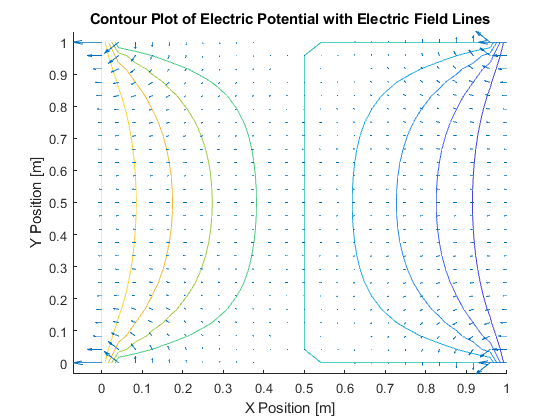



figure(4);
hold on;

contour(X,Y,Vnew);
quiver(X,Y,U,V,1.25);
title('Contour Plot of Electric Potential with Electric Field Lines');
xlabel('X Position [m]'); 
ylabel('Y Position [m]');